# get a glance of the data

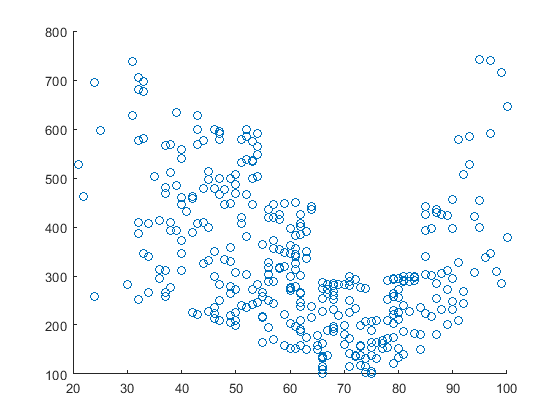


scatter(exp2.x,exp2.y)

## fit a line

[model,gof,output]=fit(exp2.x,exp2.y,"poly2")

model =      Linear model Poly2:
     model(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      0.1782  (0.1425, 0.2138)
       p2 =      -25.16  (-29.71, -20.62)
       p3 =        1147  (1010, 1285)

gof = 包含以下字段的 struct :
           sse: 5.0939e+06
       rsquare: 0.3069
           dfe: 351
    adjrsquare: 0.3029
          rmse: 120.4677


output = 包含以下字段的 struct :
        numobs: 354
      numparam: 3
     residuals: [354×1 double]
      Jacobian: [354×3 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


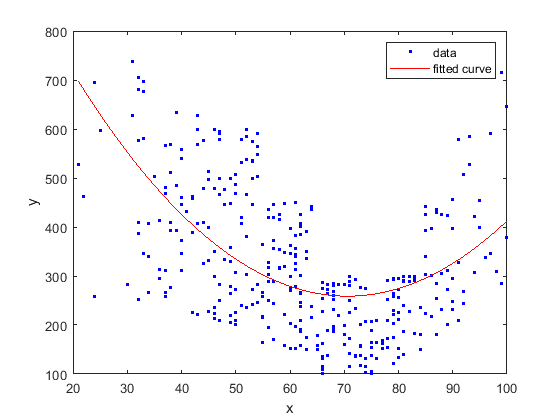

plot(model,exp2.x,exp2.y)

## let's look at the result


% this shows the goodness of the fit
gof

gof = 包含以下字段的 struct :
           sse: 5.0939e+06
       rsquare: 0.3069
           dfe: 351
    adjrsquare: 0.3029
          rmse: 120.4677


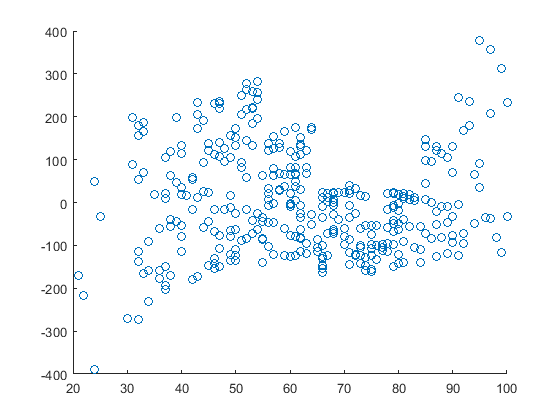

% let's plot the residuals
scatter(exp2.x,output.residuals)

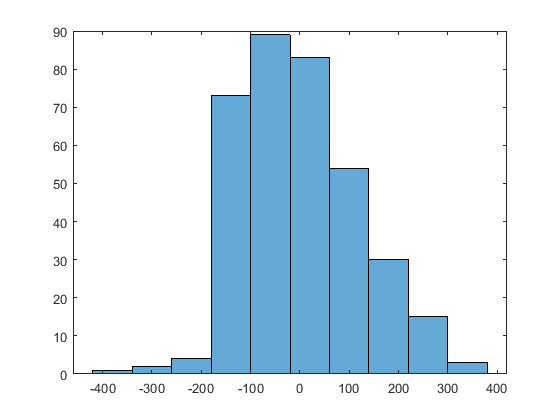

histogram(output.residuals,10)

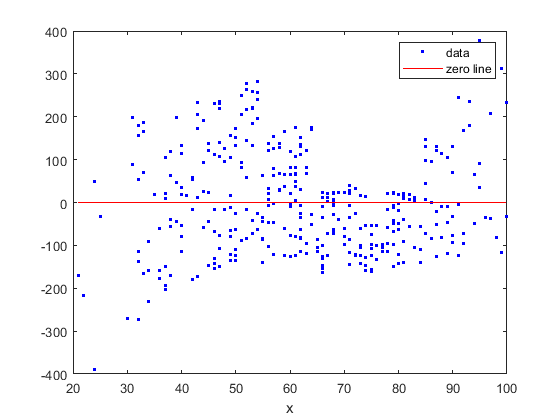

% this residual plot is better looking
plot(model,exp2.x,exp2.y,"residuals")

model

model =      Linear model Poly2:
     model(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      0.1782  (0.1425, 0.2138)
       p2 =      -25.16  (-29.71, -20.62)
       p3 =        1147  (1010, 1285)

gof

gof = 包含以下字段的 struct :
           sse: 5.0939e+06
       rsquare: 0.3069
           dfe: 351
    adjrsquare: 0.3029
          rmse: 120.4677
